clc ; clear all
E = 200e6; %in in kPa
A = 3.1415e-4; %in m^2
node = [0 0 ; 40 0 ; 40 30 ; 0 30 ];

econ = [ 1 2 ; 2 3 ; 4 3;3 1];


Nnodes = size(node,1)

Nnodes = 4

Nelements = size(econ,1)

Nelements = 4

kg = zeros(2*Nnodes);
u = zeros(2*Nnodes,1);
Fg = zeros(2*Nnodes,1);
for e = 1:Nelements
    n1 = econ(e,1)
    n2 = econ(e,2)
     
    x = [node(n1,1) ; node(n1,2) ;node(n2,1);node(n2,2)]
    
    dx = x(3) - x(1);
    dy = x(4) - x(2);
    L = sqrt(dx^2 + dy^2);
    
    c = dx/L ;
    s = dy/L;
    f = E*A/L;
    b = [ c^2 c*s ; c*s s^2 ];
    ke = zeros(4);
    ke(1:2,1:2) = b;
    ke(1:2,3:4) =-b;
    ke(3:4,1:2) = -b;
    ke(3:4,3:4)=b;
    
    ke = f.*ke;
    
    k1 = 2*n1-1 ;
    k2 = 2*n1;
    k3 = 2*n2-1 ;
    k4 = 2*n2;
    
    kg(k1:k2,k1:k2) = kg(k1:k2,k1:k2) + ke(1:2,1:2);
    kg(k1:k2,k3:k4) = kg(k1:k2,k3:k4) + ke(1:2,3:4);
    kg(k3:k4,k1:k2) = kg(k3:k4,k1:k2) + ke(3:4,1:2);
    kg(k3:k4,k3:k4) = kg(k3:k4,k3:k4) + ke(3:4,3:4);
    
end 

n1 = 1

n2 = 2

x =      0
     0
    40
     0


n1 = 2

n2 = 3

x =     40
     0
    40
    30


n1 = 4

n2 = 3

x =      0
    30
    40
    30


n1 = 3

n2 = 1

x =     40
    30
     0
     0


Global_matrix_size = size(kg)

Global_matrix_size =      8     8


kg

kg =    1.0e+03 *

    2.3750    0.6032   -1.5708         0   -0.8042   -0.6032         0         0
    0.6032    0.4524         0         0   -0.6032   -0.4524         0         0
   -1.5708         0    1.5708         0         0         0         0         0
         0         0         0    2.0943         0   -2.0943         0         0
   -0.8042   -0.6032         0         0    2.3750    0.6032   -1.5708         0
   -0.6032   -0.4524         0   -2.0943    0.6032    2.5467         0         0
         0         0         0         0   -1.5708         0    1.5708         0
         0         0         0         0         0         0         0         0


%for u2 u3 v3
fprintf('Reduced matrix after ');

Reduced matrix after 

k = [ kg(3,3) kg(3,5:6) ; kg(5:6,3) kg(5:6,5:6)];
F = [20 ; 0;-25] %in kN

F =     20
     0
   -25


U = inv(k)*F %in m

U =     0.0127
    0.0027
   -0.0104


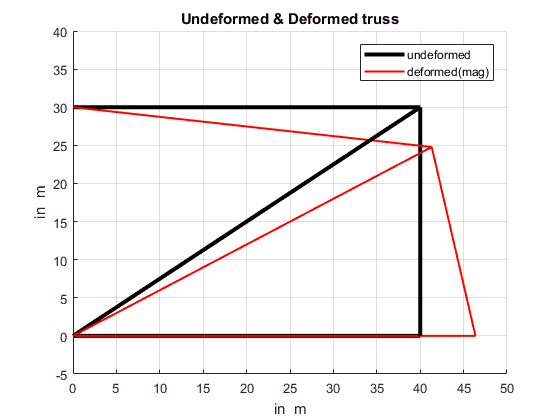


ug = zeros(8,1);
ug(3) = U(1);
ug(5) = U(2);
ug(6) = U(3);
%end results
FG = kg*ug ; %in kN (reaction)

u1 = [ ug(1) ug(2) ; 40+500*ug(3) ug(4) ; 40+500*ug(5) 30+500*ug(6) ; 0 30 ];
for e = 1:Nelements
    n1 = econ(e,1);
    n2 = econ(e,2);
    t = [node(n1,1) ; node(n1,2) ;node(n2,1);node(n2,2)];
    r = [u1(n1,1) ; u1(n1,2);u1(n2,1);u1(n2,2)];
    
    mx(e) = r(1);
    my(e) = r(2);
    
    nx(e) = r(3);
    ny(e) = r(4);
    
    Ox(e) = t(1);
    Oy(e) = t(2);
    
    ax(e) = t(3);
    ay(e) = t(4);
    title('Undeformed & Deformed truss')
    xlabel('in  m')
    ylabel('in  m')
    axis([0 50 -5 40]) %([Xmin Xmax Ymin Ymax])
    hold on
    plot( [Ox(e) ax(e)] , [Oy(e) ay(e)] , 'k','LineWidth',3)

    hold on
    plot( 1*[mx(e) nx(e)] , 1*[my(e) ny(e)] , 'r','LineWidth',1.5)
        legend('undeformed','deformed(mag)')
    grid on
    
  
end

fprintf('1.1) Nodal displacements')

1.1) Nodal displacements

fprintf('Undeformed coordinates')

Undeformed coordinates

node

node =      0     0
    40     0
    40    30
     0    30



fprintf('Deformed coordinates')

Deformed coordinates

u1 = [ ug(1) ug(2) ; 40+ug(3) ug(4) ; 40+ug(5) 30+ug(6) ; 0 30 ]

u1 =          0         0
   40.0127         0
   40.0027   29.9896
         0   30.0000



fprintf('1.2) Support reactions')

1.2) Support reactions

Reactions=FG

Reactions =   -15.8333
    3.1250
   20.0000
   21.8750
    0.0000
  -25.0000
   -4.1667
         0





for e = 1:Nelements
    n1 = econ(e,1);
    n2 = econ(e,2);
    t = [u1(n1,1) ; u1(n1,2);u1(n2,1);u1(n2,2)];
    tt=size(t);
    %element length
    le = sqrt((t(3)-t(1))^2+(t(4)-t(2))^2);
    
    c = (t(3)-t(1))/le;
    s = (t(4)-t(2))/le;
    
    a = E/le;
    b = [-c -s c s ];
    bb=size(b);
    h = b*t;
    size(h);
    Se = a*(h );
    size(Se);
end